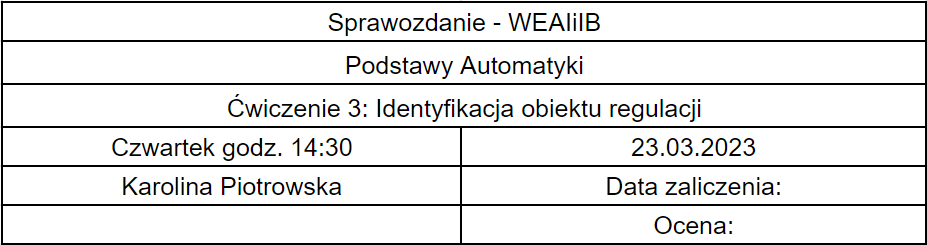

## Cele ćwiczenia

Ćwiczenie miało na celu zaznajomienie z przykładami identyfikacji parametrów modelu zastępczego rzeczywistego obiektu regulacji w środowisku MATLAB.

## Wstęp teoretyczny

Ćwiczenie polegało na wyznaczeniu parametrów nieskończenie wymiarowego systemu dynamicznego - obiektu cieplnego.

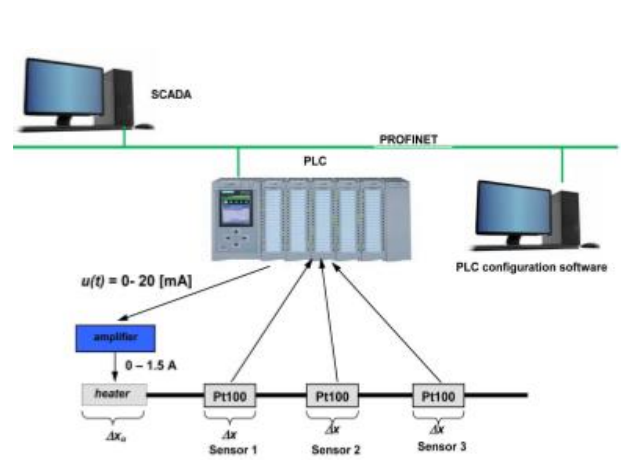

Parametry będą wyznaczone w oparciu o analizę odpowiedzi skokowej modelu. Czas pomiaru wynosi 300s z próbkowaniem 1s.

Do identyfikacji użyte zostały trzy wzory:

- Transmitancja zastępcza Kumpfmullera I rzędu z opóźnieniem


$$G(s) = \frac{ke^{-s \tau}}{Ts + 1}$$


- Transmitancja zastępcza Kumpfmullera II rzędu z opóźnieniem


$$G(s) = \frac{ke^{-s \tau}}{(T_{1}+1)(T_{2}s + 1)}$$


- Transmitancja zastępcza Strejca


$$G(s) = \frac{k}{(Ts+1)^n}$$


## Przebieg ćwiczenia

### Załadowanie danych

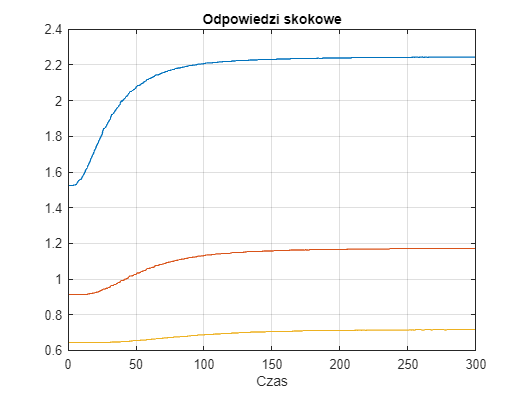

load('pomiary_3out.mat');
time = 1:1:300;
plot(time, pomiary_3out)
grid on;
title('Odpowiedzi skokowe');
xlabel('Czas')

### Czujnik 1

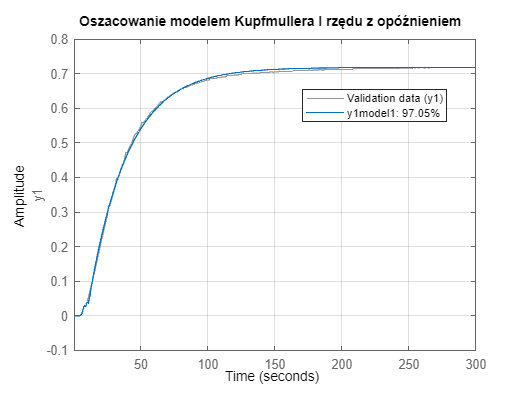

T = 29;
tau = 7.5;
T1  =4;
T2 = 28;
T1_2 = 16;
T2_2 = 20;

y1 = pomiary_3out(:, 1) - pomiary_3out(1, 1);
y2 = pomiary_3out(:, 2) - pomiary_3out(1, 2);
y3 = pomiary_3out(:, 3) - pomiary_3out(1, 3);

k1 = (y1(300, 1) - y1(1, 1)) / 1.0;
k2 = (y2(300, 1) - y2(1, 1)) / 1.0;
k3 = (y3(300, 1) - y3(1, 1)) / 1.0;

[ld1, md1] = pade(tau, 10);

[l1, m1] = series(ld1, md1, [k1], [T 1]);
[l2, m2] = series(ld1, md1, [k1], [T1*T2, T1+T2, 1]);
l3 = [k1];
m3 = [T1_2*T2_2, T1_2+T2_2, 1];

y1m1 = step(l1, m1, time);
y1m2 = step(l2, m2, time);
y1m3 = step(l3, m3, time);

u1 = ones(size(y1));
y1exper = iddata(y1, u1, 1);

y1model1 = tf(l1, m1);
y1model2 = tf(l2, m2);
y1model3 = tf(l3, m3);

compare(y1exper, y1model1, 300);
title('Oszacowanie modelem Kupfmullera I rzędu z opóźnieniem ')
legend('Location', 'best')
grid on


MSE1 = sum((y1 - y1m1).^2)

MSE1 = 0.0432

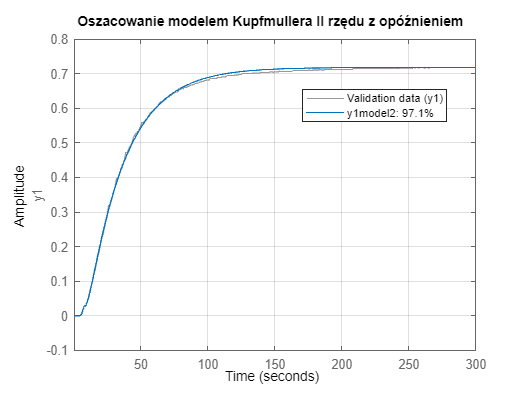


compare(y1exper, y1model2, 300);
title('Oszacowanie modelem Kupfmullera II rzędu z opóźnieniem ')
legend('Location', 'best')
grid on


MSE2 = sum((y1 - y1m2).^2)

MSE2 = 0.0234

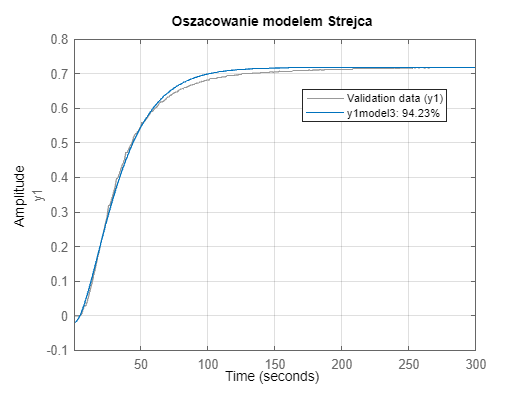


compare(y1exper, y1model3, 300);
title('Oszacowanie modelem Strejca')
legend('Location', 'best')
grid on


MSE3 = sum((y1 - y1m3).^2)

MSE3 = 0.0408

Najlepszym okazał się model Kumpfmullera II rzędu.

### Czujnik 2

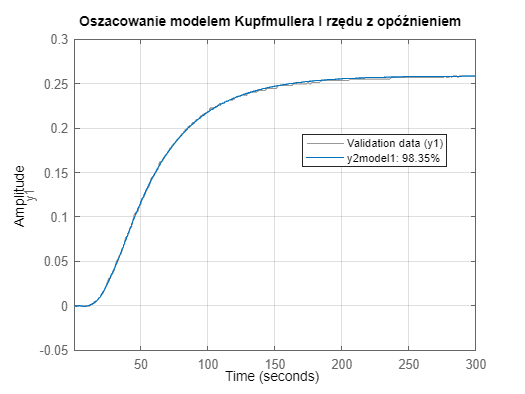

tau = 50;
T = 40;
T1 = 28;
T2 = 35;
T1_2 = 26;
T2_2 = 30;

[ld, md] = pade(tau, 10);

[l1, m1] = series([k2], [T 1], ld, md);
[l2, m2] = series([k2], [T1*T2, T1_2+T2_2, 1], ld, md);
l3 = [k2];
m3 = [T1_2*T2_2, T1_2+T2_2, 1];

y2m1 = step(l1, m1, time);
y2m2 = step(l2, m2, time);
y2m3 = step(l3, m3, time);

u2 = ones(size(y2));
y2exper = iddata(y2, u2, 1);

y2model1 = tf(l1, m1);
y2model2 = tf(l2, m2);
y2model3 = tf(l3, m3);

compare(y2exper, y2model1, 300);
title('Oszacowanie modelem Kupfmullera I rzędu z opóźnieniem ')
legend('Location', 'best')
grid on


MSE1 = sum((y2 - y2m1).^2)

MSE1 = 0.4094

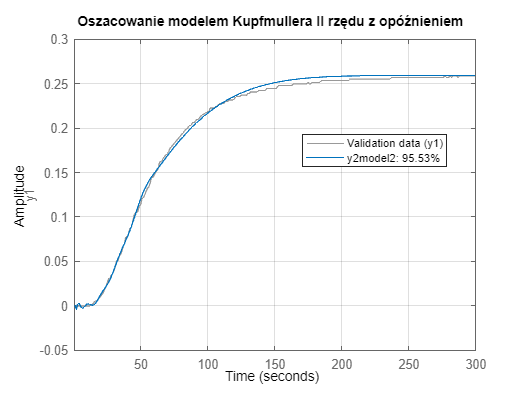


compare(y2exper, y2model2, 300);
title('Oszacowanie modelem Kupfmullera II rzędu z opóźnieniem ')
legend('Location', 'best')
grid on


MSE2 = sum((y2 - y2m2).^2)

MSE2 = 1.0359

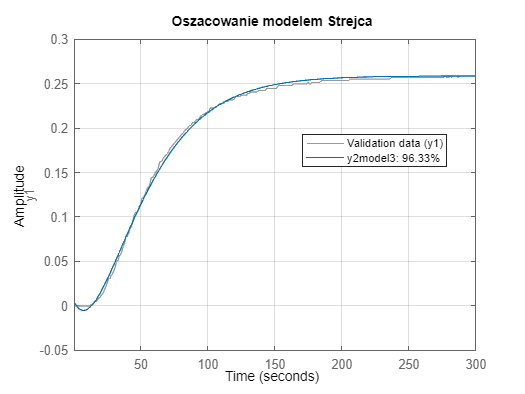


compare(y2exper, y2model3, 300);
title('Oszacowanie modelem Strejca')
legend('Location', 'best')
grid on


MSE3 = sum((y2 - y2m3).^2)

MSE3 = 0.0457

Najlepszym okazał się modeł Kumpfmullera I rzędu.

### Czujnik 3

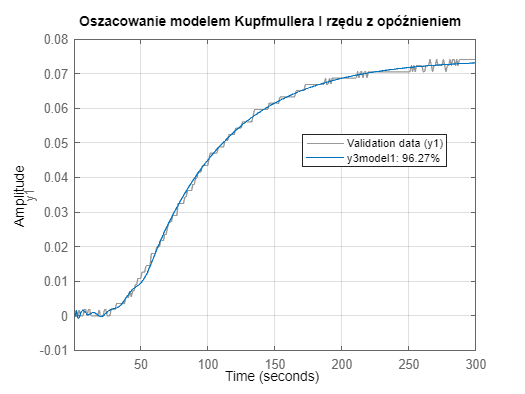

tau = 50;
T = 60;
T1 = 38;
T2 = 40;
T1_2 = 41;
T1_2 = 43;

[ld, md] = pade(tau, 10);
[l1, m1] = series([k3], [T 1], ld, md);
[l2, m2] = series([k3], [T1*T2, T1_2+T2_2, 1], ld, md);
l3 = [k3];
m3 = [T1_2*T2_2, T1_2+T2_2, 1];

y3m1 = step(l1, m1, time);
y3m2 = step(l2, m2, time);
y3m3 = step(l3, m3, time);

u3 = ones(size(y3));
y3exper = iddata(y3, u3, 1);

y3model1 = tf(l1, m1);
y3model2 = tf(l2, m2);
y3model3 = tf(l3, m3);

compare(y3exper, y3model1, 300);
title('Oszacowanie modelem Kupfmullera I rzędu z opóźnieniem ')
legend('Location', 'best')
grid on


MSE1 = sum((y3 - y3m1).^2)

MSE1 = 0.0026

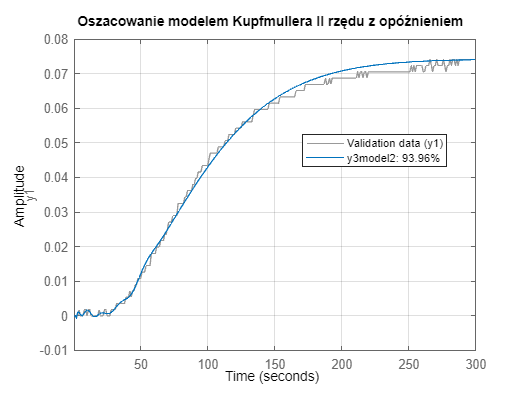


compare(y3exper, y3model2, 300);
title('Oszacowanie modelem Kupfmullera II rzędu z opóźnieniem ')
legend('Location', 'best')
grid on


MSE2 = sum((y3 - y3m2).^2)

MSE2 = 0.0224

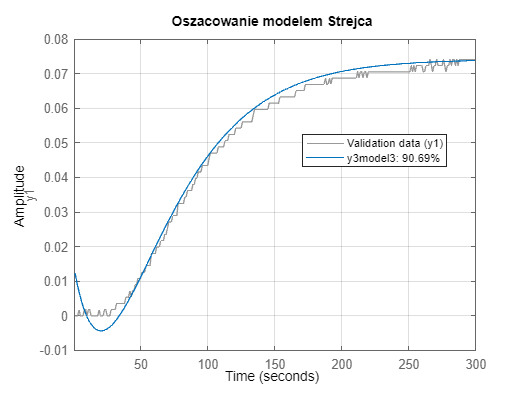


compare(y3exper, y3model3, 300);
title('Oszacowanie modelem Strejca')
legend('Location', 'best')
grid on


MSE3 = sum((y3 - y3m3).^2)

MSE3 = 0.0258

Najlepszym okazał się model Kumpfmullera I rzędu.

## Wnioski

Ćwiczenie pozwoliło zapoznać się z różnymi modelami identyfikacji. Najgorzej wypadły modele tworzone w oparciu o transmitancję Strejca, lecz nie oznacza to, iż ten model jest gorszy - istnieją takie odpowiedzi skokowe, które byłyby przez niego dobrze idektyfikowane.